# The decoding error disaggregated across spatial-directional bins

Load the example session from Mouse2022:

n_reps = 80;

sm = SessManager;
d = sm.cons_usable(SessManager.special_sessions_usable_index_single('Mouse2022'));

Perform decoding, saving the full set of predictions:

[me_bins, me_bins_shuf] = deal(zeros(n_reps, d.opt.n_bins));
t_ = tic;
%parpool(8);
WaitMessage = parfor_wait(n_reps);
parfor j = 1:n_reps
    [~, ~, ps, ks, ~] = d.basic_decode(false,[],[]);
    [~, ~, ps_shuf, ks_shuf, ~] = d.basic_decode(true,[],[]);
    toc(t_)
    
    me_bins(j,:) = binwise_error(ks, ps, d.opt);
    me_bins_shuf(j,:) = binwise_error(ks_shuf, ps_shuf, d.opt);
    WaitMessage.Send;
end
WaitMessage.Destroy;

Use ps (the predictions) and ks (the true bins) to find the binwise error rate:

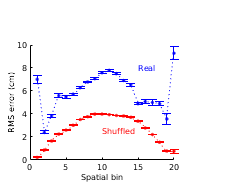

figure;
errorbar(1:d.opt.n_bins, mean(me_bins), 1.96*std(me_bins)./sqrt(n_reps), 'b.:');
hold on
errorbar(1:d.opt.n_bins, mean(me_bins_shuf), 1.96*std(me_bins_shuf)./sqrt(n_reps), 'r.:');
xlabel 'Spatial bin'
ylabel 'RMS error (cm)'

text(15, 8, 'Real', 'Color', 'b');
text(10, 2.5, 'Shuffled', 'Color', 'r');

figure_format([1.5 1.2]);
Utils.printto('supfigs_code', 'decoder_by_bins.pdf');

save decoder_by_bins.mat me_bins me_bins_shuf

n_reps = 16;
d_neu = 30;
n_neu = size(d.data_tensor, 1);

n_size = unique([1, d_neu:d_neu:n_neu, n_neu]);
num_n_size = numel(n_size);

[me_bins, me_bins_shuf] = deal(zeros(num_n_size, n_reps, d.opt.n_bins));
t_ = tic;
%parpool(8);
WaitMessage = parfor_wait(n_reps*num_n_size);
for k = 1:num_n_size
    parfor j = 1:n_reps
        [~, ~, ps, ks, ~] = d.basic_decode(false,n_size(k),[]);
        [~, ~, ps_shuf, ks_shuf, ~] = d.basic_decode(true,n_size(k),[]);
        toc(t_)

        me_bins(k,j,:) = binwise_error(ks, ps, d.opt);
        me_bins_shuf(k,j,:) = binwise_error(ks_shuf, ps_shuf, d.opt);
        WaitMessage.Send;
    end
    fprintf('Finished %d size (%d of %d)\n', n_size(k), k, num_n_size);
end

Finished 1 size (1 of 18)
Finished 30 size (2 of 18)
Finished 60 size (3 of 18)
Finished 90 size (4 of 18)
Finished 120 size (5 of 18)
Finished 150 size (6 of 18)
Finished 180 size (7 of 18)
Finished 210 size (8 of 18)
Finished 240 size (9 of 18)
Finished 270 size (10 of 18)
Finished 300 size (11 of 18)
Finished 330 size (12 of 18)
Finished 360 size (13 of 18)
Finished 390 size (14 of 18)
Finished 420 size (15 of 18)
Finished 450 size (16 of 18)
Finished 497 size (18 of 18)


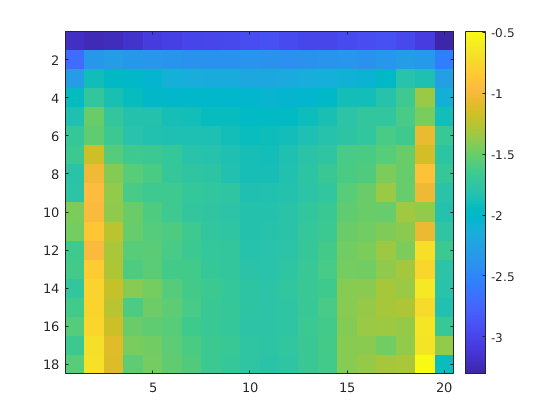

figure;
imse_bins = 1./me_bins.^2;
imse_bins_shuf = 1./me_bins_shuf.^2;

imagesc(log10(squeeze(mean(imse_bins,2)))); colorbar

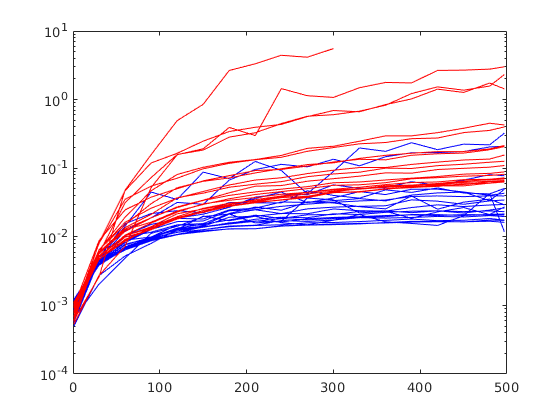

figure;
plot(n_size, squeeze(mean(imse_bins,2)), 'b');
hold on;
plot(n_size, squeeze(mean(imse_bins_shuf,2)), 'r');
set(gca, 'YScale', 'log');

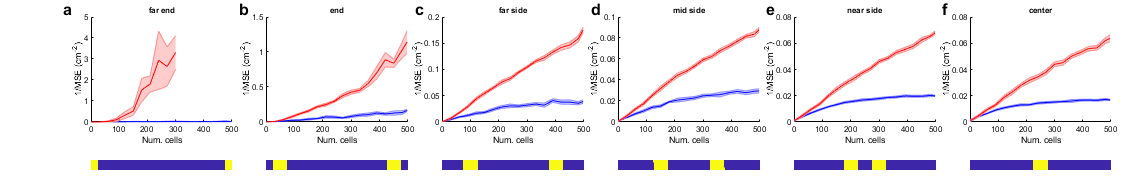

bin_groups = {[1 20], [2 3 18 19], [4 5 16 17], [6 7 14 15], [8 9 12 13], [10 11]};
bg_names = {'far end', 'end', 'far side', 'mid side', 'near side', 'center'};

p = Pub(30,5,'rows',4,'columns',6, 'hspacing', 0.03, 'layout', {{1:3,1},{1:3,2},{1:3,3},{1:3,4},{1:3,5},{1:3,6},{4,1},{4,2},{4,3},{4,4},{4,5},{4,6}});

for bg_i = 1:numel(bin_groups)
    bg = bin_groups{bg_i};
    
    p.panel(bg_i, 'xlab', 'Num. cells', 'ylab', '1/MSE (cm^{-2})', 'title', bg_names{bg_i}, 'x_shift', -0.03);
    x = squeeze(mean(imse_bins(:, :, bg),3)).';
    x_shuf = squeeze(mean(imse_bins_shuf(:, :, bg),3)).';
    shadedErrorBar(n_size, x, {@mean, @(x)sem(x)*1.96}, 'lineprops', 'b');
    hold on;
    shadedErrorBar(n_size, x_shuf, {@mean, @(x)sem(x)*1.96}, 'lineprops', 'r');
    title(sprintf('Bin group %d', bg_i));
    xlabel 'Num. cells'
    ylabel IMSE
    
end

for bg_i = 1:numel(bin_groups)
    bg = bin_groups{bg_i};
    track_map = ismember(1:20, bg);
    p.panel(bg_i + numel(bin_groups), 'x_shift', -0.03, 'letter', '');
    imagesc(track_map);
    axis off
end

p.format;
Utils.printto('events_figs/f2_events/decoding_curves', 'decoding_curves_by_bin.pdf');

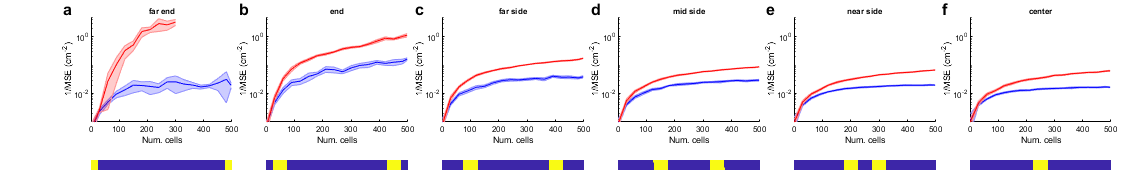

p = Pub(30,5,'rows',4,'columns',6, 'hspacing', 0.03, 'layout', {{1:3,1},{1:3,2},{1:3,3},{1:3,4},{1:3,5},{1:3,6},{4,1},{4,2},{4,3},{4,4},{4,5},{4,6}});

for bg_i = 1:numel(bin_groups)
    bg = bin_groups{bg_i};
    
    p.panel(bg_i, 'xlab', 'Num. cells', 'ylab', '1/MSE (cm^{-2})', 'title', bg_names{bg_i}, 'x_shift', -0.03);
    x = squeeze(mean(imse_bins(:, :, bg),3)).';
    x_shuf = squeeze(mean(imse_bins_shuf(:, :, bg),3)).';
    shadedErrorBar(n_size, x, {@mean, @(x)sem(x)*1.96}, 'lineprops', 'b');
    hold on;
    shadedErrorBar(n_size, x_shuf, {@mean, @(x)sem(x)*1.96}, 'lineprops', 'r');
    title(sprintf('Bin group %d', bg_i));
    xlabel 'Num. cells'
    ylabel IMSE
    
    ylim([1e-3 5]);
    set(gca, 'YScale', 'log');
    
end

for bg_i = 1:numel(bin_groups)
    bg = bin_groups{bg_i};
    track_map = ismember(1:20, bg);
    p.panel(bg_i + numel(bin_groups), 'x_shift', -0.03, 'letter', '');
    imagesc(track_map);
    axis off
end

p.format;
Utils.printto('events_figs/f2_events/decoding_curves', 'decoding_curves_by_bin_logscale.pdf');

Function for computing the disaggregated error across spatial bins (but still aggregated based on direction of motion)

function me_bins = binwise_error(ks, ps, opt)
ks_s = ceil(ks/2);
ps_s = ceil(ps/2);

me_bins = zeros(1, opt.n_bins);
for i = 1:opt.n_bins
    k = ks_s(ks_s == i);
    p = ps_s(ks_s == i);
    
    %me_bins(i) = mean(abs(k - p)) * opt.bin_width;
    me_bins(i) = sqrt(mean((k - p).^2)) * opt.bin_width;
end
end